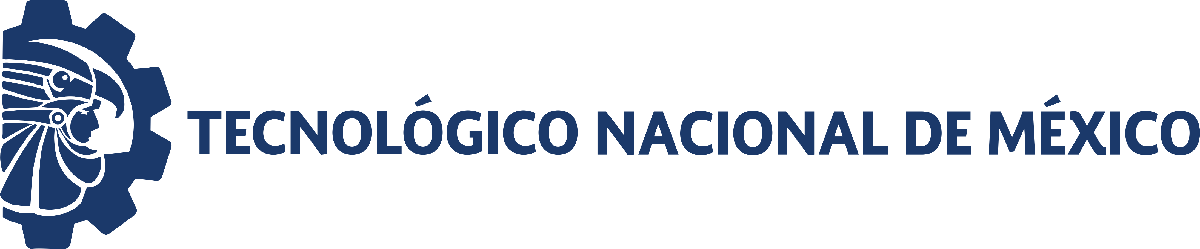                                 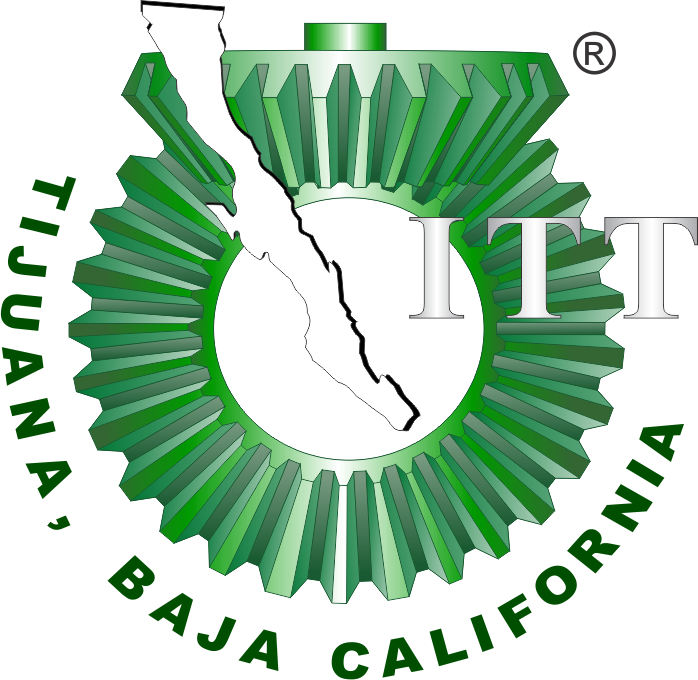

# Práctica: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

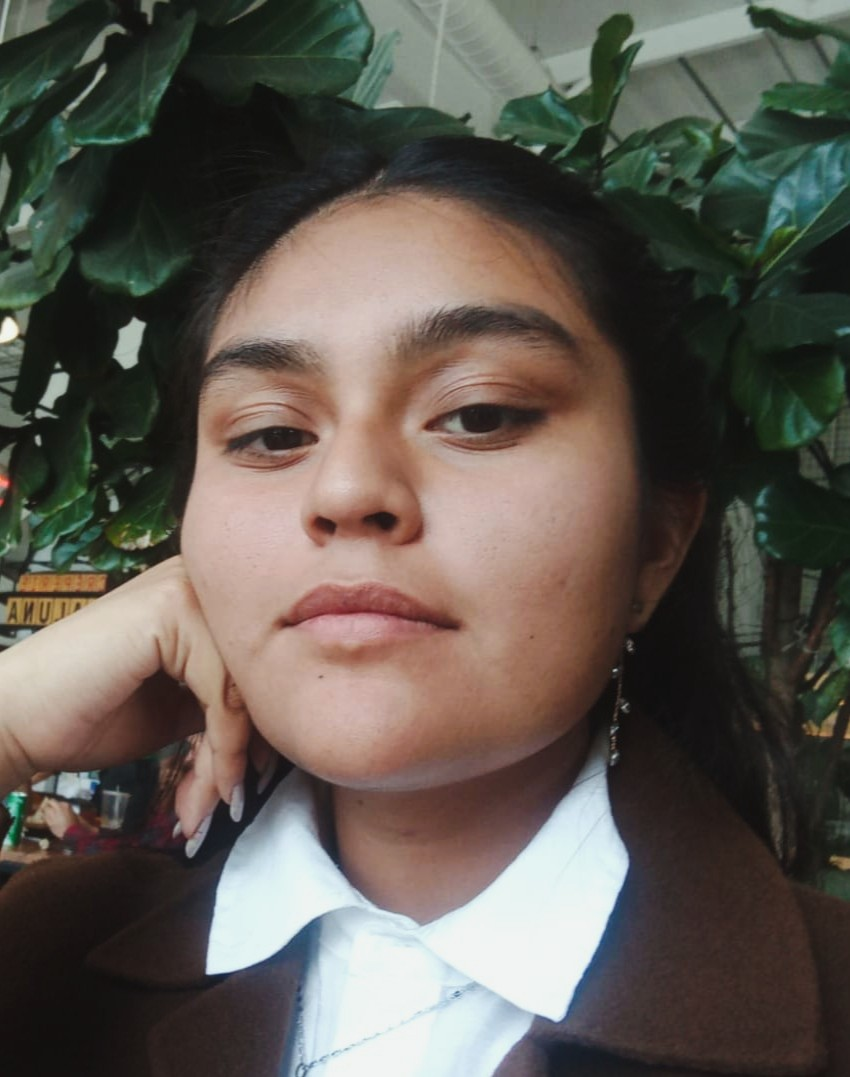

Nombre del alumno: **Bricia Idalia Arellano Salones**

Número de control: **22211746**

Correo institucional: **L22211746@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

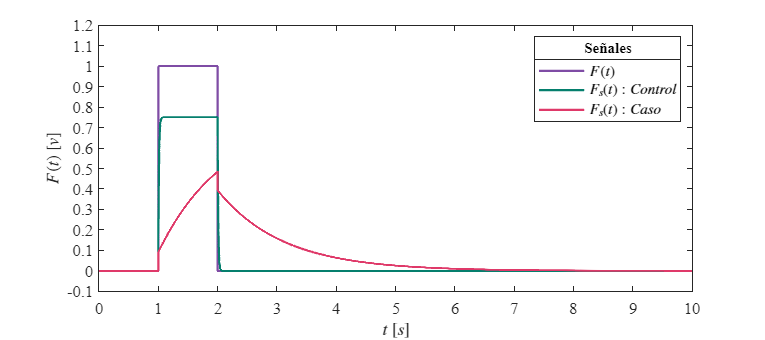

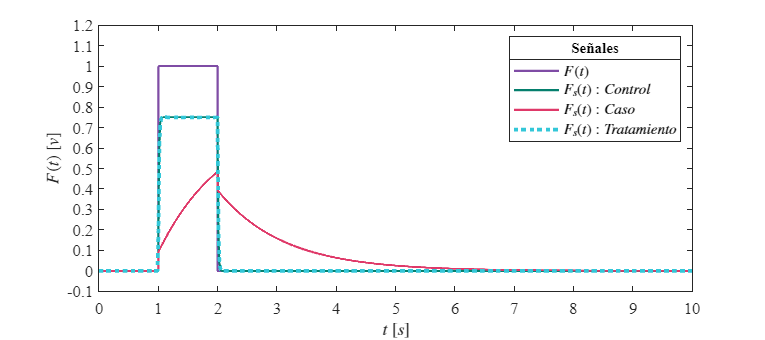

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend; 
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('sistema/F(t)', 'Amplitude', '1');
x = sim(file, parameters);
plotsignals(x.t, x.F, x.Fs1, x.Fs2, x.Fs3);

## Función: Respuesta a las señales

function plotsignals (t,F, Fs1, Fs2, Fs3)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [0.4980,    0.2980,    0.6471;
                0.0196,    0.4980,    0.4275;
                0.8745,    0.2235,    0.4118;
                0.2000,    0.7804,    0.8471;
                1.0000,    0.5529,    0.0784;
                0.4824,    0.1765,    0.2627];
    colororder(mycolors);
    plot(t, F, t, Fs1, t, Fs2,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    L = legend('$F(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$');
    title(L,'Señales', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$F(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.1, 1.2]); yticks(-0.1:0.1:1.2);
    exportgraphics(gcf, 'SM_Lazo abierto.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'SM_Lazo abierto.png', 'ContentType', 'vector')
    set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    colororder(mycolors);
    p1 = plot(t, F, '-', t, Fs1, '-', t, Fs2, '-', t, Fs3, ':', ...
      'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p1(4),'LineWidth', 2.5)
    L1 = legend('$F(t)$','$F_{s}(t): Control$','$F_{s}(t): Caso$','$F_{s}(t): Tratamiento$');
    title(L1,'Señales', 'FontSize', 10);
    set(L1, 'Interpreter', 'Latex', 'FontSize', 10,'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$F(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    ylim([-0.1, 1.2]); yticks(-0.1:0.1:1.2);
    exportgraphics(gcf, 'SM_Lazo cerrado.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'SM_Lazo cerrado.png', 'ContentType', 'vector')
end